# Specify Text to be Treated as Empty or Comments

Load the file `data2.csv` and preview its contents in a text editor. A screen shot is shown below. Notice the file contains data that can be interpreted as comments and other entries such as `'NA'` or `'na'` that may indicate empty fields.

filename = 'data2.csv';

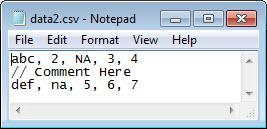

Designate the input that `textscan` should treat as comments or empty values and scan the data into `C`. 

fileID = fopen(filename);
C = textscan(fileID,'%s %n %n %n %n','Delimiter',',',...
'TreatAsEmpty',{'NA','na'},'CommentStyle','//');
fclose(fileID);

Display the output.

celldisp(C)

*Copyright 2012 The MathWorks, Inc.*